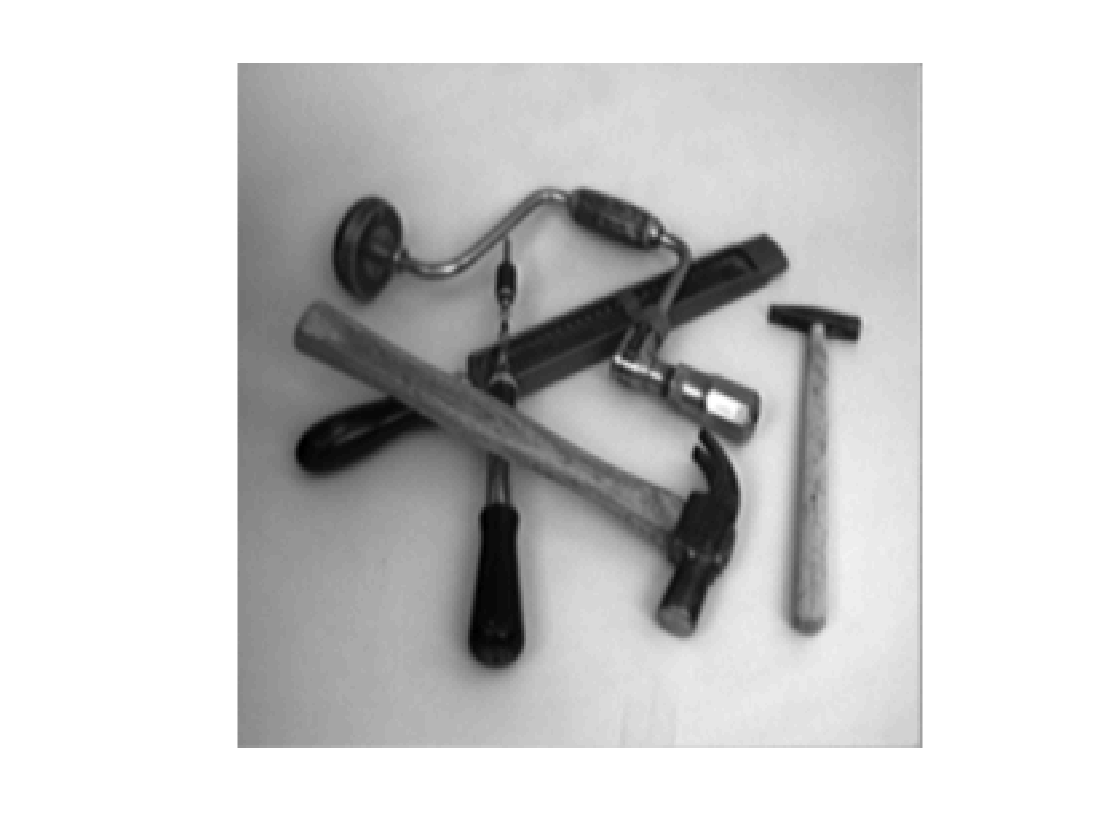

% sobel- Discrete differential operator, computes approximation of gradient
% on image intensity function. 

tools = gaussfft(few256, 0.4); 
% edge detection  algorithm (sobel operator)
showgrey(tools);

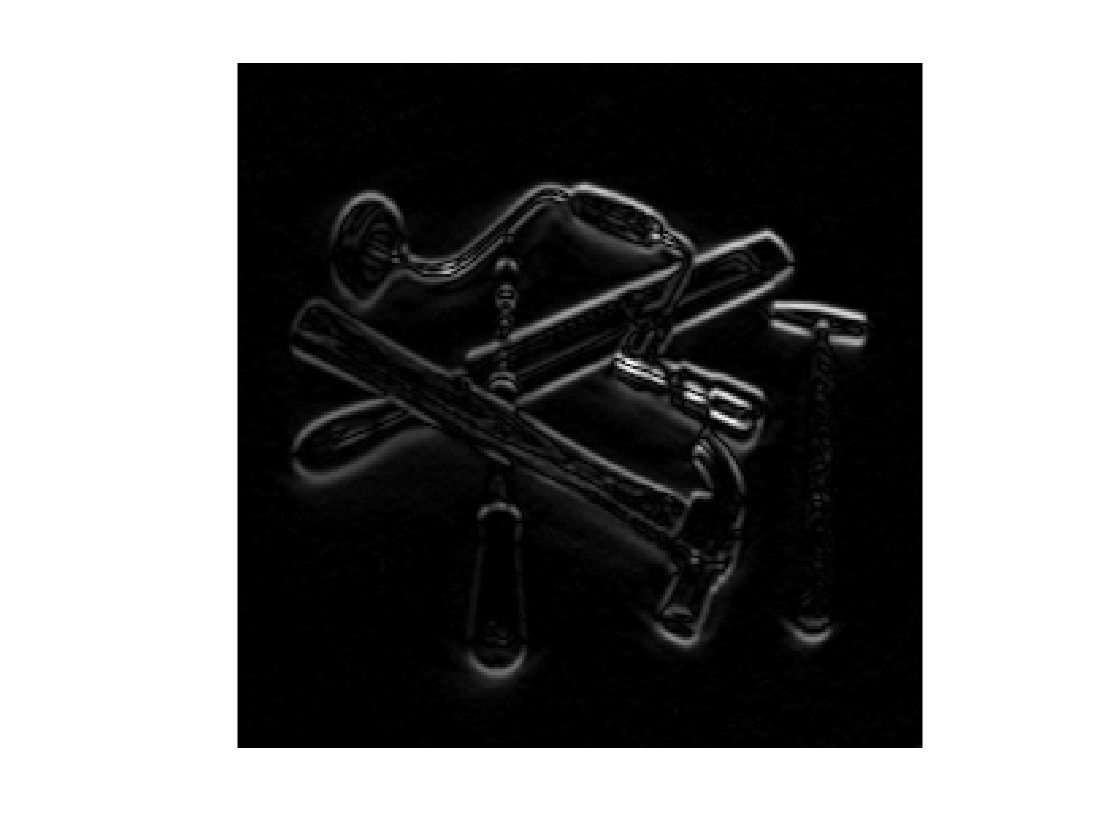

% apply a mask in x
maskx = [-1, -2, -1; 0, 0, 0; 1, 2, 1]; % vertical sobel derivative
% multiply each 3 b 3 picle by maskx, make it pixles, keep shifting to the
% right.
result = conv2(maskx, tools, 'same');
[r, c] = size(tools); % rows and columns 
output = zeros(r-3, c-3);
for idx = 1:(r-3)
    for jdx = 1:(c-3)
    
        bwsquare = bwdl(idx:(idx+2), jdx:(jdx+2)); % where we are atm 
        %res = maskx.*bwsquare;
        output(idx, jdx) = sum(sum(maskx.*bwsquare));
        %output(idx, jdx) = conv2(maskx, bwsquare, 'valid');
    end
end
figure()
Gx = output;
showgrey(sqrt(output.^2))

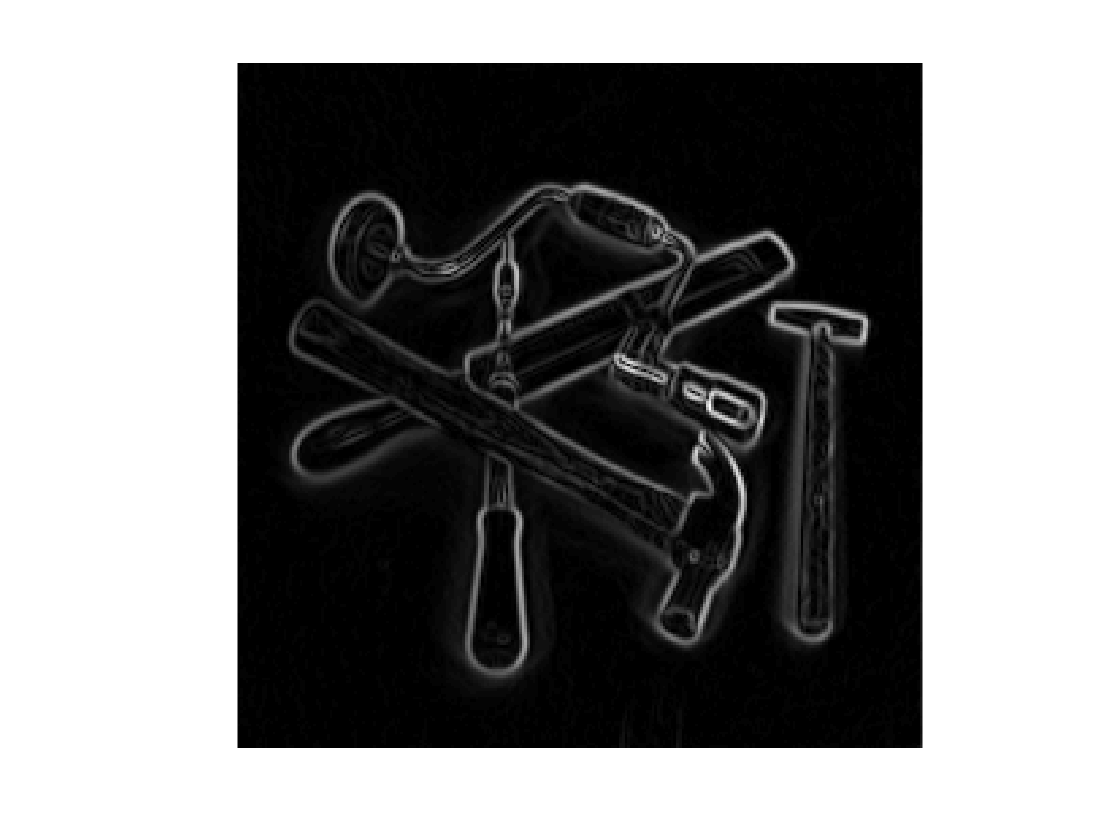

%figure()
%imshow(Gx)
% apply another mask in y
masky = [-1 0, 1; -2, 0, 2; -1, 0, 1];  % horizontal sobel derivative

bwdl = tools ;
for idx = 1:(r-3)
    for jdx = 1:(c-3)
        bwsquare = bwdl(idx:(idx+2), jdx:(jdx+2)); % where we are atm 
        %res = maskx.*bwsquare;
        output(idx, jdx) = sum(sum(masky.*bwsquare));
    end
end
figure()
Gy = output;
% % showgrey(sqrt(Gy.^2)) %sqrt normalize, black & white,otherwise grey. 
%figure()
%imshow(Gy)

% normalize results of both masks 
G = sqrt(Gx.^2 + Gy.^2);
%plot the results
figure()
showgrey(G)

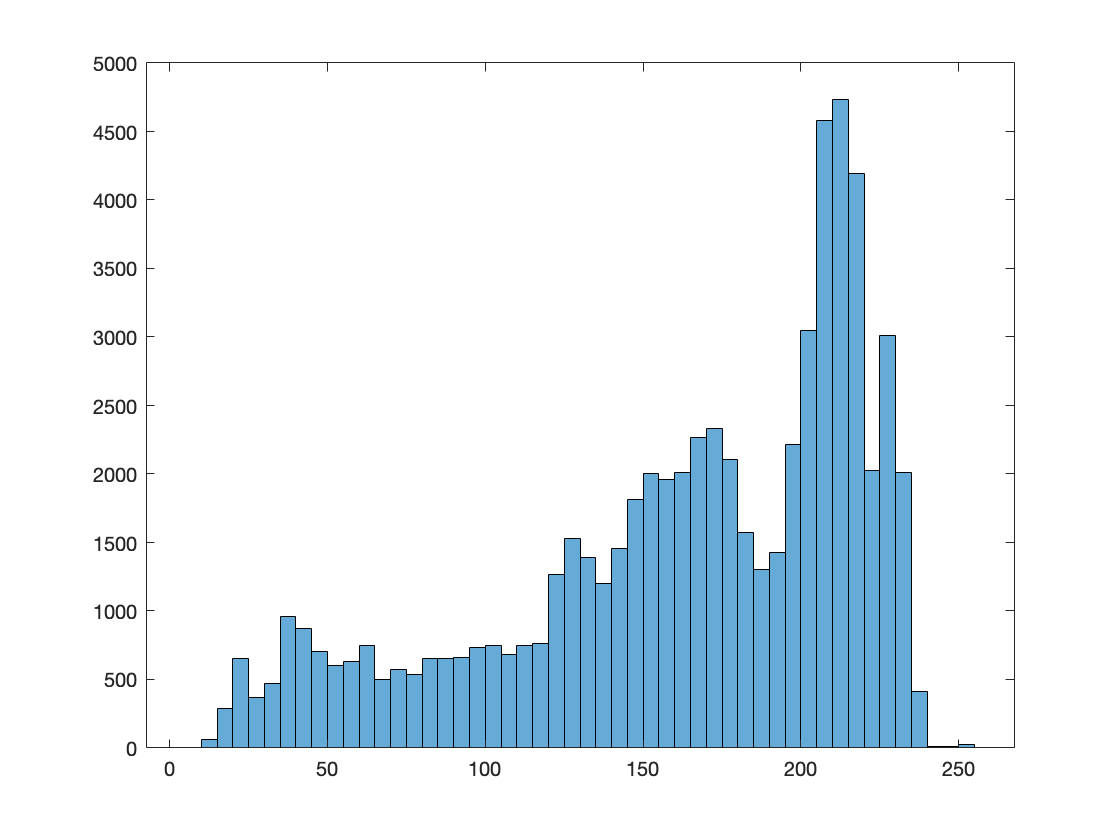


histogram(tools)

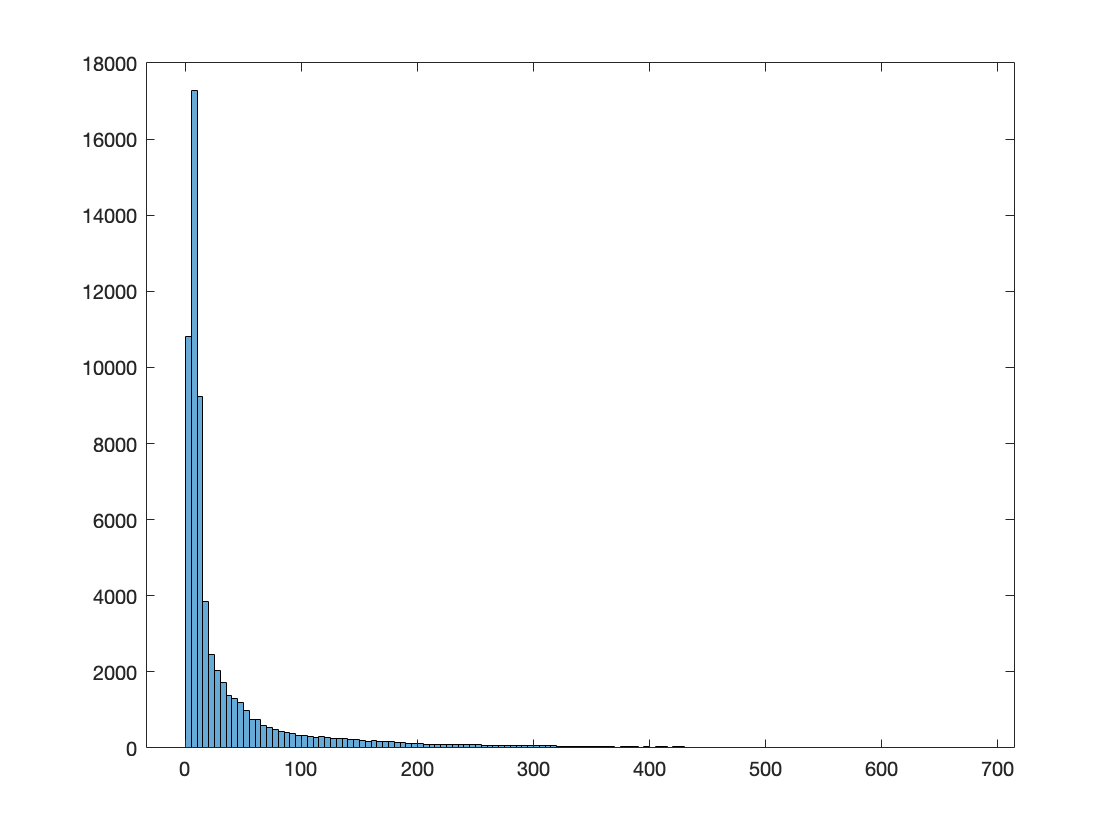

histogram(G)

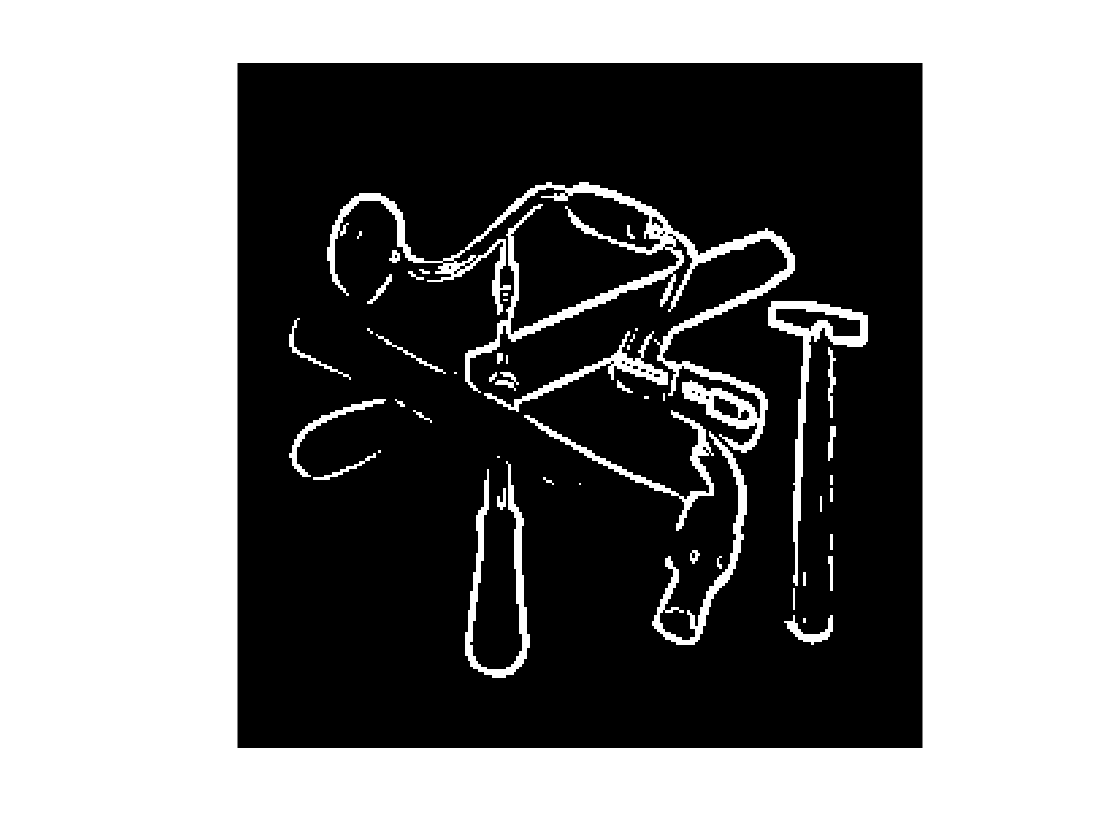

showgrey((G - 150) > 0) % threshhold 80-1900?? 

% the bigger threshold, the thinner edges and we reject smaller thickness
%G_blurr = gaussfft(G, 0.8);
%showgrey(G_blurr)
